# Graphical Fit for TCLab Dynamics

**Objective**: Collect step response data from the TCLab and compute parameters of an FOPDT model.

A First Order Plus Dead Time (FOPDT) of the Temperature Control Lab (TCLab) is the following:


$$\tau_p \frac{dT'}{dt} = -T' + K_p \, Q'\left(t-\theta_p\right)$$


where $T'=T-T_{ss}$ and $Q'=Q-Q_{ss}$ are deviation variables with steady-state initial conditions $T_{ss}=23^\circ\text{C}$ and $Q_{ss}=0\%$. Perform a step test with heater 1 starting at 0% for 0.5 minutes (30 seconds) and then step the heater to 70% for 7.5 minutes. Create a plot of the temperature response over 8 minutes that also shows the heater level (%). Sample source code for generating the response is provided below.

Initialize the script location

clc; clear all; close all;
tmp = matlab.desktop.editor.getActive;
directory = fileparts(tmp.Filename);


n = 8 * 60;  % number of seconds to test
time = linspace(0, n, n+1);

% Collect data
filename = "L06_TCLab_data.csv";
absolute_path = fullfile(directory, filename);

Step Test heater at 70% for 8 minutes, and save that data for later

try % try to read from file first
    A = readmatrix(absolute_path)
    tm_ = A(:,1);
    T1_ = A(:,2);
    Q1_ = A(:,3);
    disp('TCLab Data read from file')
    
catch % if file can not be found, simulate
    try 
        % initialize lab
        lab = tclab;
        
        % loop through
        T1_ = zeros(n+1, 1);
        Q1_ = zeros(n+1, 1);
        tm_ = zeros(n+1, 1);
        tic;
        for i=1:n+1
            tm_(i) = toc;
            if tm_(i) > 30
                Q1_(i) = 70;
            end
            lab.Q1(Q1_(i));
            T1_(i) = lab.T1;
            plot(tm_(1:i), T1_(1:i), 'r.')
            xlabel('Time (sec)')
            ylabel('Temperature (C)')
            pause(1-min(1,toc-tm_(i)));
        end
        lab.off;
        clear lab;
        
        % save
        A = [tm_ T1_]
        writematrix(A, absolute_path, 'Delimiter', ',')
        
    catch % if an error, turn off heater and close
        lab.off;
        clear lab;
    end
    
end

### Exercise

USING THE GRAPH GENERATED, CALCULATE VALUES OF $K_p$, $\tau_p$, AND $\theta_p$ WITH THEIR RESPECTIVE UNITS 

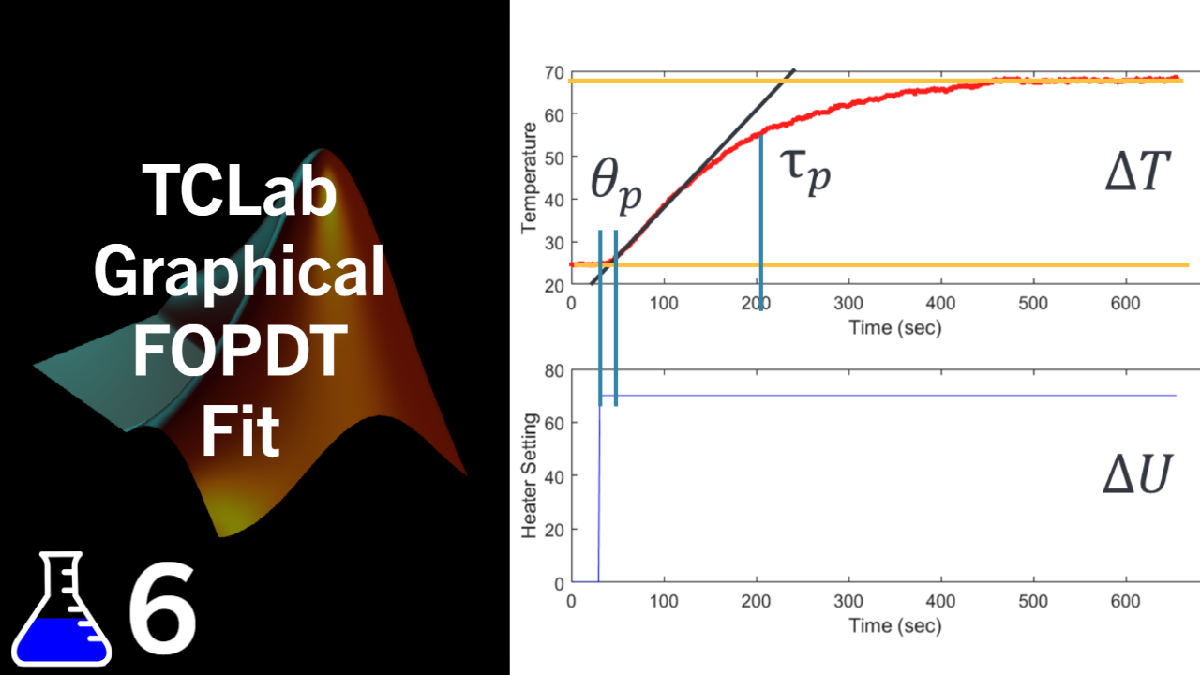

### [View Solution Video](https://youtu.be/eAZz-indbVc)